%空間６自由度マニピュレータの基本モデル作成(rigidbodyjointを使う)
%DH法で座標系を設定し、オイラで座標系間の変換を行う。
%Matlab 2021a, Robotics System Toolboxが必要

まず、ワークスペースをクリア

clear

## 鉄柱objectを追加

ironPillar = importrobot('pillar30_URDF_stl.urdf');  %urdfにgeometry設定
ironPillarconfig = homeConfiguration(ironPillar);
%show(ironPillar,config,'Collisions','on','Visuals','on'); %configに従ったrobotを表示

## 鉄柱L鋼の平面、点モデル

１番目鋼材（斜め鋼材50x50x6）

%S1...S10は、10平面に属する点の姿勢と位置の同時変換行列, pillarObjPointsは、点の位置ベクトル
Lx1=0.044; Ly1=0.044; Lz1=0.430; Lt1=0.006;
%構造物のL鋼1への同時変換行列計算
tformModel= trvec2tform([0.210 0 0.265]);
tformModel= tformModel*axang2tform([1 0 0 pi/3]);
tformModel= tformModel*axang2tform([0 0 1 pi]);

[S11,S12,S13,S14,S15,S16,S17,S18,S19,S110,obj1CenPoints,obj1Points]=func_pillarModelPoints(Lx1,Ly1,Lz1,Lt1,tformModel);

%plot3(obj1Points(:,1),obj1Points(:,2),obj1Points(:,3),'*');
%plot3(obj1CenPoints(:,1),obj1CenPoints(:,2),obj1CenPoints(:,3),'*');

２番目鋼材（左側75x75x9）

%S1...S10は、10平面に属する点の姿勢と位置の同時変換行列, pillarObjPointsは、点の位置ベクトル
Lx2=0.066; Ly2=0.066; Lz2=0.269; Lt2=0.009;
%構造物のL鋼1への同時変換行列計算
tformModel= trvec2tform([0.216 0.183 0.265]);
tformModel= tformModel*axang2tform([0 0 1 pi]);

[S21,S22,S23,S24,S25,S26,S27,S28,S29,S210,obj2CenPoints,obj2Points]=func_pillarModelPoints(Lx2,Ly2,Lz2,Lt2,tformModel);

%plot3(obj2Points(:,1),obj2Points(:,2),obj2Points(:,3),'*');
%plot3(obj2CenPoints(:,1),obj2CenPoints(:,2),obj2CenPoints(:,3),'*');

3番目の鋼材(右側75x75x9)

%S1...S10は、10平面に属する点の姿勢と位置の同時変換行列, pillarObjPointsは、点の位置ベクトル
Lx2=0.066; Ly2=0.066; Lz2=0.269; Lt2=0.009;
%構造物のL鋼1への同時変換行列計算
tformModel= trvec2tform([0.216 -0.183 0.265]);
tformModel= tformModel*axang2tform([0 1 0 pi]);

[S31,S32,S33,S34,S35,S36,S37,S38,S39,S310,obj3CenPoints,obj3Points]=func_pillarModelPoints(Lx2,Ly2,Lz2,Lt2,tformModel);

%plot3(obj3Points(:,1),obj3Points(:,2),obj3Points(:,3),'*')
%plot3(obj3CenPoints(:,1),obj3CenPoints(:,2),obj3CenPoints(:,3),'*');

## ６自由度ロボットの目標ポーズ運動学解析

L1,L2,L3の長さを変更しながら、目標点の位置とその点での姿勢をエンドエフェクタでとらせることができるか調べる。また、その時の各関節にかかるトルクも求める。条件として、関節の可動域は制限しない（制限したい場合は、robot.Bodies.Joint.PositionLimitsで制限)。


P_RoI(:,:,1)=S11(:,:,3); 
P_RoI(:,:,2)=S11(:,:,4); 
P_RoI(:,:,3)=S12(:,:,1)*axang2tform([0 1 0 -pi/6]);  %リンクが他鋼材と干渉しないように
P_RoI(:,:,4)=S12(:,:,2)*axang2tform([0 1 0 pi/6]);   %平面の法線（刷毛の方向）を変更
P_RoI(:,:,5)=S14(:,:,3)*axang2tform([0 1 0 -pi/6]); 
P_RoI(:,:,6)=S14(:,:,4);
P_RoI(:,:,7)=S21(:,:,3); 
P_RoI(:,:,8)=S21(:,:,4); 
P_RoI(:,:,9)=S31(:,:,3); 
P_RoI(:,:,10)=S31(:,:,4);
P_RoI(:,:,11)=S11(:,:,3)*trvec2tform([0 0 Lz1/2]); 

シミュレーション条件

pnt_S =1; 
pnt_F=11;       %調査pointのスタート、終了番号。  終了番号は２以上にすること。 
L1 = 0.270;         %link 3の長さ
L2 = 0.13;  %L2長さのスタート、終了長さ
L3 = 0.18;  %L3長さのスタート、終了長さ
L4 = 0;              %link 4の長さ
L5 = 0;              %link 5の長さ
L6 = 0.15;            %link 6の長さ（メカニカルポイントから手先先端原点までの距離）

#### シミュレーション開始


 
            robot = func_sixLinkCollisionModel(L1,L2,L3,L4,L5,L6); %robot bodytree生成
            robot.Bodies{1,1}.Joint.PositionLimits=[-170*3.14/180 170*3.14/180];  
            robot.Bodies{1,2}.Joint.PositionLimits=[-90*3.14/180 170*3.14/180];  
            robot.Bodies{1,3}.Joint.PositionLimits=[-100*3.14/180 90*3.14/180];  
            robot.Bodies{1,4}.Joint.PositionLimits=[-170*3.14/180 170*3.14/180];  
            robot.Bodies{1,5}.Joint.PositionLimits=[-150*3.14/180 150*3.14/180];   
            robot.Bodies{1,6}.Joint.PositionLimits=[-175*3.14/180 175*3.14/180];    
            robot.Gravity=[0,0,-9.8];     %重力加速度設定

逆運動学ソルバーの準備

            q0 = homeConfiguration(robot);        %初期configuration
            ndof = length(q0);                    %自由度の大きさ
            qs = zeros(1, ndof);                  %countごとに、2dofのconfを返す行列を割り当てる

逆運動学ソルバー作成

            ik = inverseKinematics('RigidBodyTree', robot);
            ik.SolverParameters.SolutionTolerance = 0.001;  %成功判定誤差閾値
            ik.SolverParameters.MaxIterations=1500;
            weights = [0.1, 0.1, 0.1, 1, 1, 1];       %姿勢と位置の重み　姿勢角0.01rad
            endEffector = 'tool';
            qInitial = q0;

目標コンフィギュレーションの設定

            %%%%%%
 k=1; cnt=1;
for pnt = pnt_S:1:pnt_F
            PointTform = P_RoI(:,:,pnt); %S21(:,:,4);                            %関心点の同時変換行列
            tform = PointTform*axang2tform([0 1 0 -pi/2]);      %刷毛姿勢への変換(目標姿勢)
            tform = tform*axang2tform([0 0 1 pi/2]);            %

逆運動学計算

            [qSol solInfo] = ik(endEffector,tform,weights,qInitial); % 逆運動学計算
            qs = qSol;                          %関節configuration解
            gT = gravityTorque(robot,qs);       %重力補償トルク
            Error=solInfo.PoseErrorNorm;        %目標ポーズとの誤差ノルム
            ErrorFlag=solInfo.ExitFlag;         %終了プラグ  1:成功, 2:最大半報回数到達 
            

表示のために保存

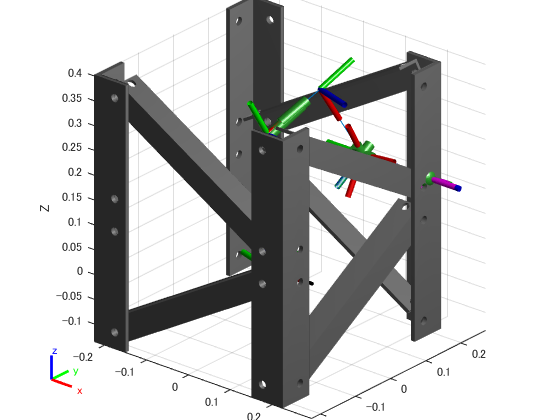

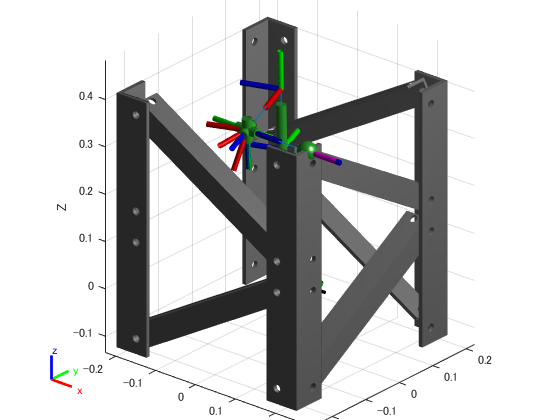

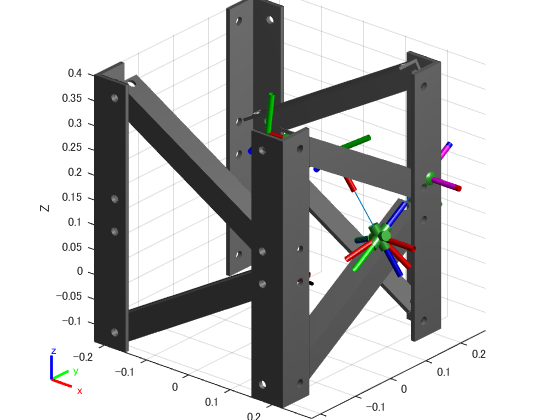

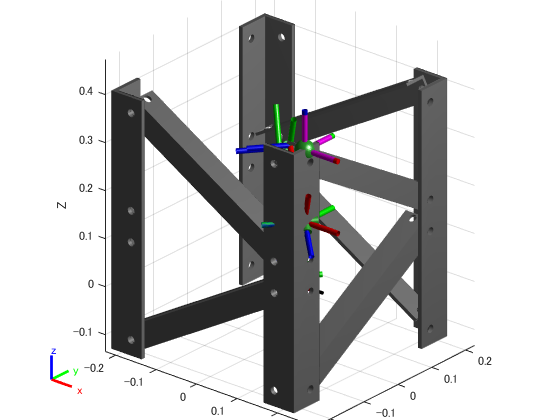

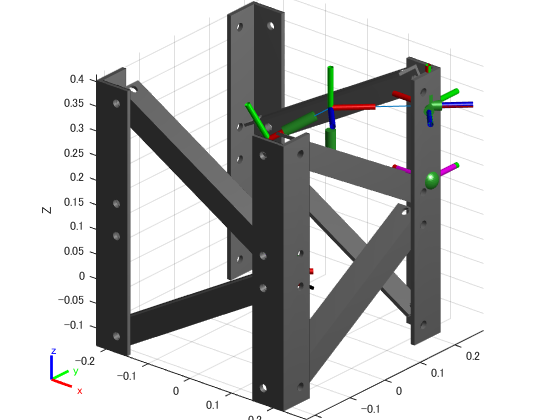

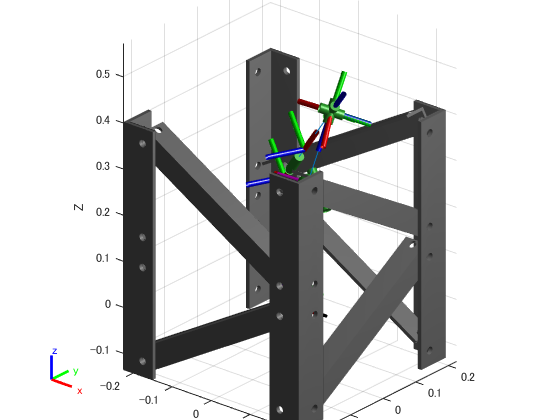

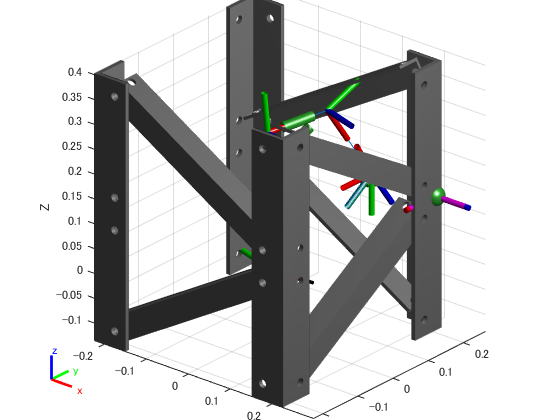

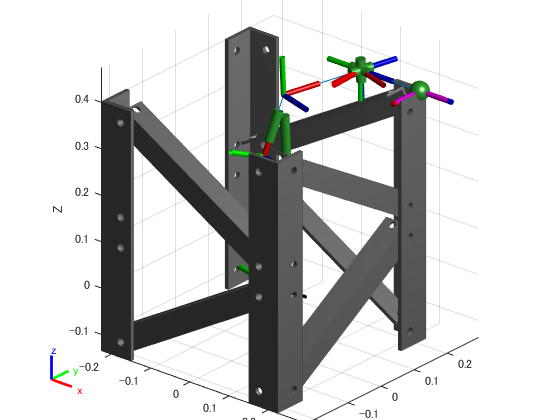

            R_Config(cnt,:)=[pnt L2 L3 qs' gT'];  %シミュレーション全カウンタ
            R_Err(k,:)=Error;                %(L2×L3×pnt)の多次元配列    
            R_ErrF(k,:)=ErrorFlag;
            R_cnt(k,:)=cnt;
            R_gT2n(k,:)=abs(gT(2));
            R_gT3n(k,:)=abs(gT(3));
            R_gT4n(k,:)=abs(gT(4));
            R_gT5n(k,:)=abs(gT(5));
            R_gT6n(k,:)=abs(gT(6));
            R_qs1(k,:)=qs(1);
            R_qs2(k,:)=qs(2);
            R_qs3(k,:)=qs(3);
            R_qs4(k,:)=qs(4);
            R_qs5(k,:)=qs(5);
            R_qs6(k,:)=qs(6);          
            cnt=cnt+1;

            k=k+1;
end

### 結果プロット

% c=11;     %a:L2のインディクス, b:L3のインディクス, c:points番号のインディクス
% figure
% hold off
% grid on
% robot = func_sixLinkCollisionModel(L1,R_Config(R_cnt(c),2),R_Config(R_cnt(c),3),L4,L5,L6);
% %show(ironPillar,ironPillarconfig,'Collisions','on','Visuals','on'); %configに従ったrobotを表示
% show(robot,R_Config(R_cnt(c),4:9)','Collisions','on','Visuals','on');      %最初のコンフィギュレーション
% ax = gca;
% ax.Projection = 'orthographic';   %正投影設定
% axis([-1 1 -1 1 -1 1]);         %表示軸の範囲 x- x+ y- y+
% xlabel X;
% ylabel Y;
% zlabel Z;
% view(40,25);
% camproj('orthographic');           %正投影


for c=1:1:11     %a:L2のインディクス, b:L3のインディクス, c:points番号のインディクス
%subplot(2,6,c)
figure
hold off
grid on
robot = func_sixLinkCollisionModel(L1,R_Config(R_cnt(c),2),R_Config(R_cnt(c),3),L4,L5,L6);
show(robot,R_Config(R_cnt(c),4:9)','Collisions','on','Visuals','on');      %最初のコンフィギュレーション
%show(ironPillar,ironPillarconfig,'Collisions','on','Visuals','on'); %configに従ったironPillarを表示
 axis([0.1 0.25 -0.3 0.3 0 0.6]);         %表示軸の範囲 x- x+ y- y+
 axis equal
 xlabel X;
 ylabel Y;
 zlabel Z;
view(40,25);
camproj('orthographic');           %正投影
end



%figure
%hold off
%q0 = homeConfiguration(robot);
%show(robot,q0,'Collisions','on','Visuals','on');  
%show(ironPillar,ironPillarconfig,'Collisions','on','Visuals','on'); %configに従ったrobotを表示
%show(robot,R_Config(R_cnt(c),4:9)','Collisions','on','Visuals','on'); 
